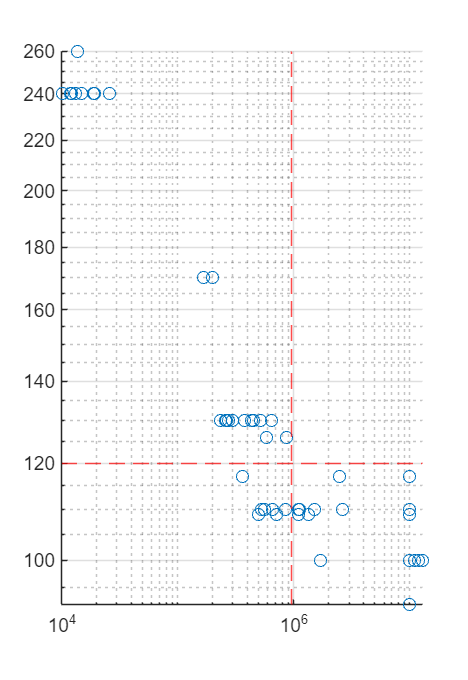

clear all
clf
format shortg

% data = xlsread("fatigue_data.xlsx")r;
load("fatigue_data.mat")
% data_size = size(data)

scatter(N,S)
yscale log
xscale log
grid("on")

N_D = 9.5*1e5;
S_D = 120;
yline(S_D, 'r--')
xline(N_D, 'r--')

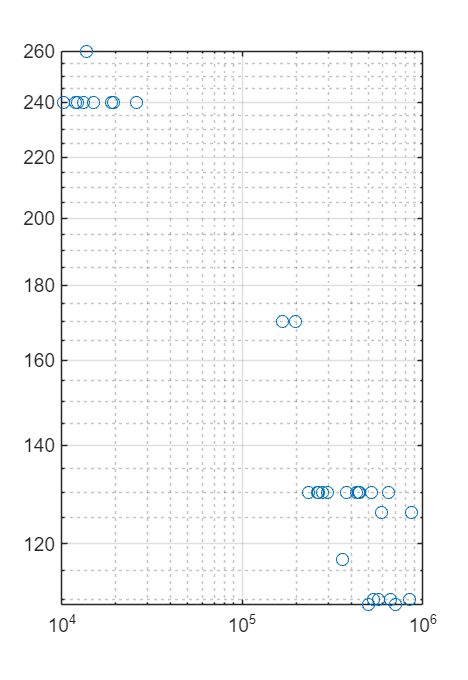


data = [N, S, RO];

data2 = [];

for i = 1:length(N)
    if N(i) < N_D && RO(i)==0
        data2(end+1,1:2) = data(i,1:2);
    end
end

N2 = data2(:,1);
S2 = data2(:,2);

figure(1)
loglog(N2, S2,"o")
grid("on")


N2_log = log10(N2);
S2_log = log10(S2);

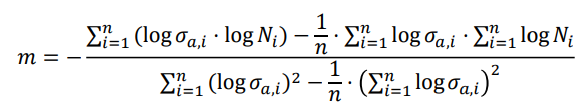

m = m_fun(S2,N2) % made as a matlab fuction in m_fun.m

m =         4.863


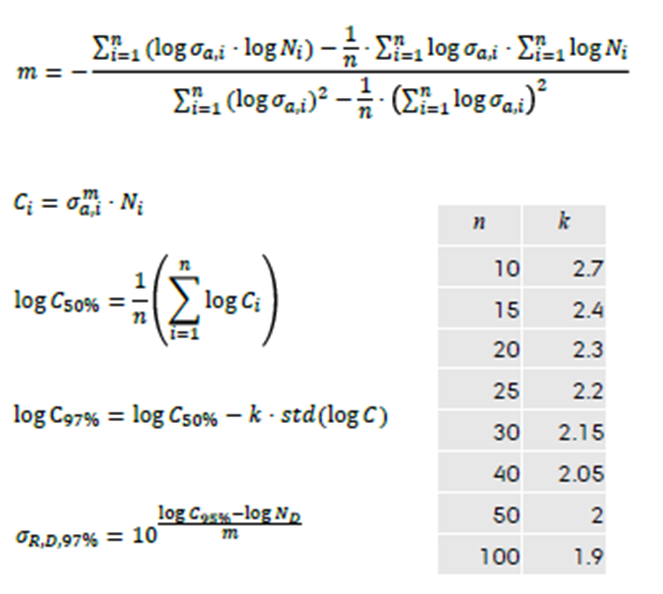



C_i = N2 .* S2.^m

C_i =    9.8705e+15
   5.0496e+15
   8.5366e+15
   1.2329e+16
   8.2127e+15
   4.4208e+15
   5.2782e+15
   5.6784e+15
   7.2028e+15
   4.9734e+15



C_50_log10 = sum(log10(C_i))/length(N2)

C_50_log10 =         15.82



C_50 = 10^C_50_log10

C_50 =    6.6127e+15



sigma_RD_50 = 10^((C_50_log10 - log10(N_D))/m)

sigma_RD_50 =        105.68



N_1_plot =1e4;
S_plot = (C_50 / N_1_plot)^(1/m) % laver vore start punkt ved at isolere sigma

S_plot =        269.59


s_dev = std(log10(C_i))

s_dev =       0.16561


n = length(S2)

n =     31


k = 2.15

k =          2.15


C_97_log10 = C_50_log10 - k*s_dev

C_97_log10 =        15.464



sigma_RD_97 = 10^((C_97_log10 - log10(N_D))/m)

sigma_RD_97 =        89.287



C_97 = 10^C_97_log10

C_97 =    2.9129e+15


S_plot_97 = (C_97 / N_1_plot)^(1/m) % laver vore start punkt ved at isolere sigma

S_plot_97 =        227.76


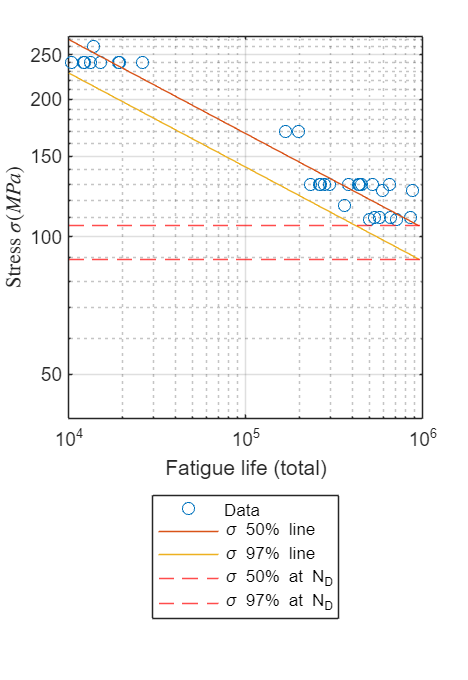


fig=gcf;
fig.Position(3:4)=[550,800];
loglog(N2, S2,"o", DisplayName='Data')
hold on
loglog([N_1_plot, N_D], [S_plot, sigma_RD_50], DisplayName='\sigma 50% line')
loglog([N_1_plot, N_D], [S_plot_97, sigma_RD_97], DisplayName='\sigma 97% line')

yline(sigma_RD_50,"r--", DisplayName='\sigma 50% at N_D')
yline(sigma_RD_97,"r--", DisplayName='\sigma 97% at N_D')
xlabel("Fatigue life (total)")
ylabel("Stress $\sigma (MPa)$", Interpreter="latex")
ylim([40,S_plot+5])
legend('Location','southoutside')
grid("on")
hold off

S150 = 150; %MPa
N_S150 = C_97/S150^m

N_S150 =         76223



N_20000 = 1e5;
S_20000 = (C_97/N_20000)^(1/m)

S_20000 =        141.85
